# Solución de raíces con el método de bisección

#### Ejemplo 1 


$$x-\cos\left(x\right)=0$$


Definición de la función y su gráfica

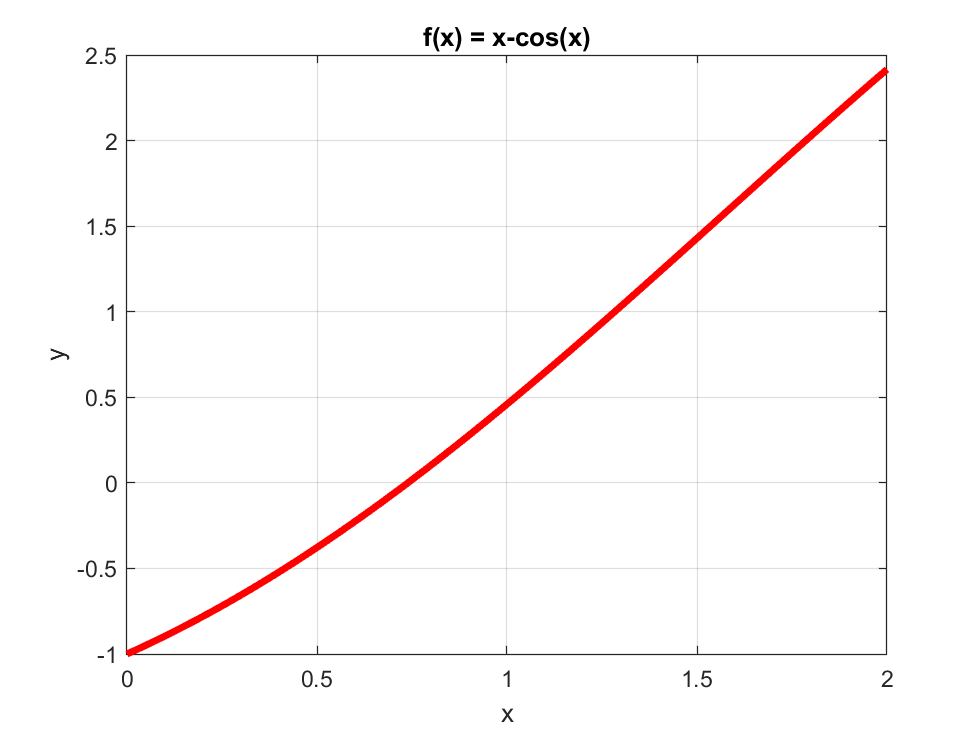

f = @(x) x-cos(x);

x = linspace(0, 2, 100);
plot(x, f(x), 'r', 'linewidth', 3)
grid on
xlabel('x')
ylabel('y')
title('f(x) = x-cos(x)')

Solución de la ecuación

xa = 0;
xb = 2;
errmax = 0.1;
[xr, fr, err] = bisection(f, xa, xb, errmax);

xa: 0  xb: 2  xm: 1  fa: -1  fb: 2.4161  fm: 0.4597  error: 100
xa: 0  xb: 1  xm: 0.5  fa: -1  fb: 0.4597  fm: -0.37758  error: 100
xa: 0.5  xb: 1  xm: 0.75  fa: -0.37758  fb: 0.4597  fm: 0.018311  error: 33.3333
xa: 0.5  xb: 0.75  xm: 0.625  fa: -0.37758  fb: 0.018311  fm: -0.18596  error: 20
xa: 0.625  xb: 0.75  xm: 0.6875  fa: -0.18596  fb: 0.018311  fm: -0.085335  error: 9.0909
xa: 0.6875  xb: 0.75  xm: 0.71875  fa: -0.085335  fb: 0.018311  fm: -0.033879  error: 4.3478
xa: 0.71875  xb: 0.75  xm: 0.73438  fa: -0.033879  fb: 0.018311  fm: -0.0078747  error: 2.1277
xa: 0.73438  xb: 0.75  xm: 0.74219  fa: -0.0078747  fb: 0.018311  fm: 0.0051957  error: 1.0526
xa: 0.73438  xb: 0.74219  xm: 0.73828  fa: -0.0078747  fb: 0.0051957  fm: -0.0013451  error: 0.5291
xa: 0.73828  xb: 0.74219  xm: 0.74023  fa: -0.0013451  fb: 0.0051957  fm: 0.0019239  error: 0.26385
xa: 0.73828  xb: 0.74023  xm: 0.73926  fa: -0.0013451  fb: 0.0019239  fm: 0.00028901  error: 0.1321
xa: 0.73828  xb: 0.73926  xm: 0.

disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%") 

x = 0.73877  f(x) = -0.00052816  Error:0.066094%


#### Ejemplo 2


$$xe^x=1$$
 

Definición de la función y su gráfica

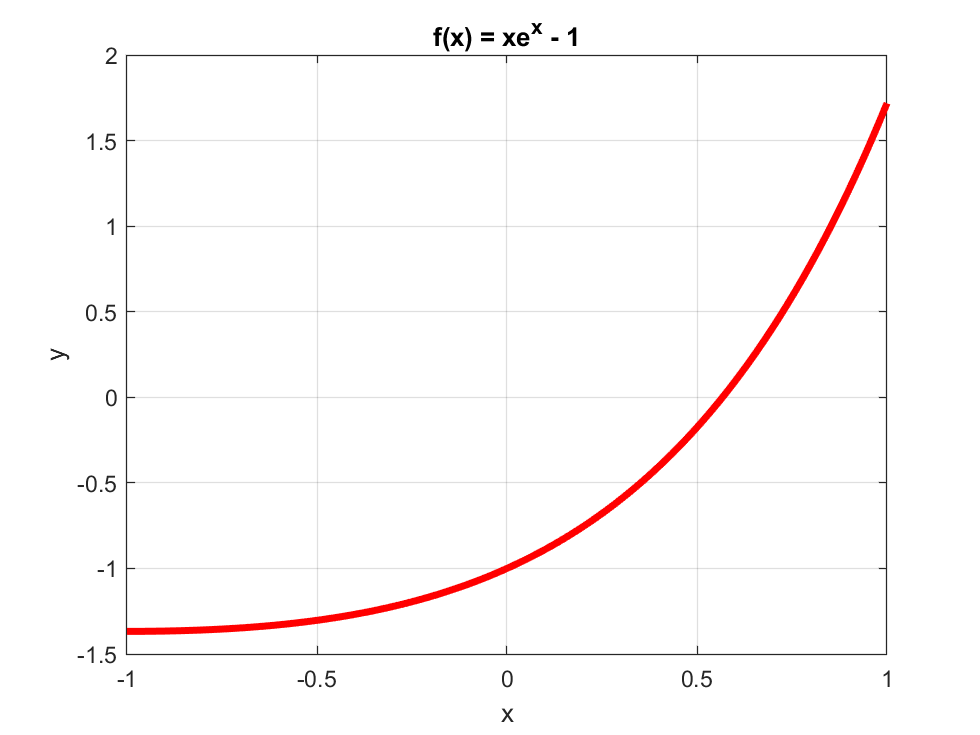

f = @(x) x.*exp(x) - 1;

x = linspace(-1, 1, 100);
plot(x, f(x), 'r', 'linewidth', 3)
grid on
xlabel('x')
ylabel('y')
title('f(x) = xe^x - 1')

Solución de la ecuación

xa = -1;
xb = 1;
errmax = 0.1;
[xr, fr, err] = bisection(f, xa, xb, errmax);

xa: -1  xb: 1  xm: 0  fa: -1.3679  fb: 1.7183  fm: -1  error: 4.503599627370496e+17
xa: 0  xb: 1  xm: 0.5  fa: -1  fb: 1.7183  fm: -0.17564  error: 100
xa: 0.5  xb: 1  xm: 0.75  fa: -0.17564  fb: 1.7183  fm: 0.58775  error: 33.3333
xa: 0.5  xb: 0.75  xm: 0.625  fa: -0.17564  fb: 0.58775  fm: 0.16765  error: 20
xa: 0.5  xb: 0.625  xm: 0.5625  fa: -0.17564  fb: 0.16765  fm: -0.012782  error: 11.1111
xa: 0.5625  xb: 0.625  xm: 0.59375  fa: -0.012782  fb: 0.16765  fm: 0.075142  error: 5.2632
xa: 0.5625  xb: 0.59375  xm: 0.57813  fa: -0.012782  fb: 0.075142  fm: 0.030619  error: 2.7027
xa: 0.5625  xb: 0.57813  xm: 0.57031  fa: -0.012782  fb: 0.030619  fm: 0.00878  error: 1.3699
xa: 0.5625  xb: 0.57031  xm: 0.56641  fa: -0.012782  fb: 0.00878  fm: -0.0020354  error: 0.68966
xa: 0.56641  xb: 0.57031  xm: 0.56836  fa: -0.0020354  fb: 0.00878  fm: 0.0033637  error: 0.34364
xa: 0.56641  xb: 0.56836  xm: 0.56738  fa: -0.0020354  fb: 0.0033637  fm: 0.00066198  error: 0.17212
xa: 0.56641  xb: 0.567

disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = 0.56689  f(x) = -0.00068724  Error:0.086133%


#### Ejemplo 3


$$x\:\log_{10}\left(x\right)=1.2$$


Definición de la función y su gráfica

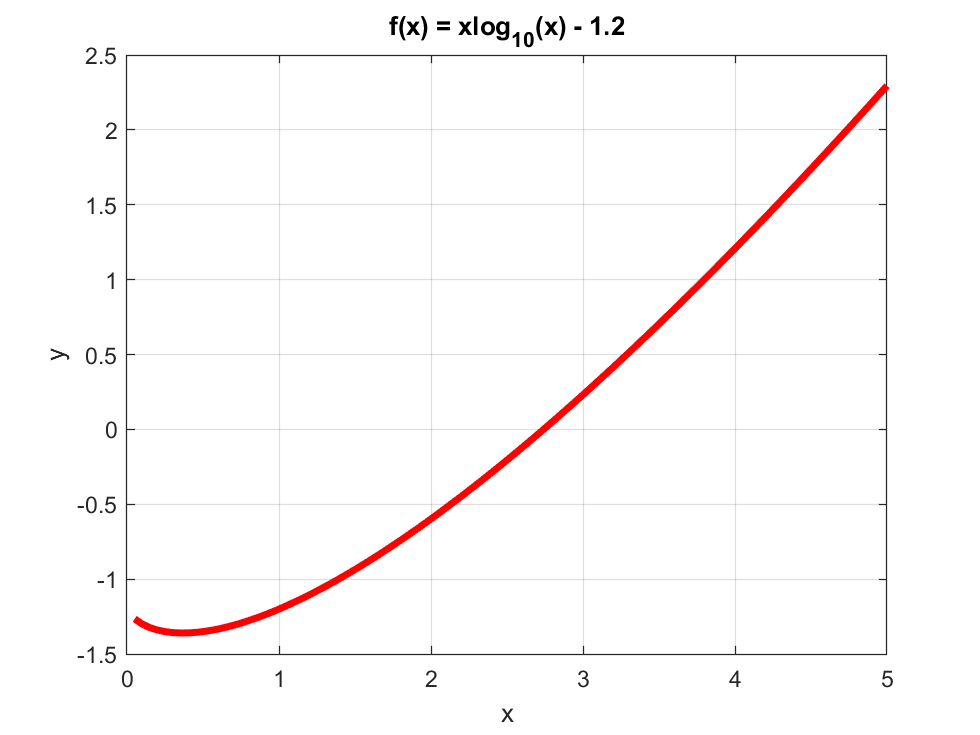

f = @(x) x.*log10(x) - 1.2;

x = linspace(0, 5, 100);
plot(x, f(x), 'r', 'linewidth', 3)
grid on
xlabel('x')
ylabel('y')
title('f(x) = xlog_1_0(x) - 1.2')

Solución de la ecuación

xa = -1;
xb = 5;
errmax = 0.1;
[xr, fr, err] = bisection(f, xa, xb, errmax);

xa: -1  xb: 5  xm: 2  fa: -1.2-1.3644i  fb: 2.2949  fm: -0.59794  error: 150
xa: 2  xb: 5  xm: 3.5  fa: -0.59794  fb: 2.2949  fm: 0.70424  error: 42.8571
xa: 2  xb: 3.5  xm: 2.75  fa: -0.59794  fb: 0.70424  fm: 0.0081649  error: 27.2727
xa: 2  xb: 2.75  xm: 2.375  fa: -0.59794  fb: 0.0081649  fm: -0.3078  error: 15.7895
xa: 2.375  xb: 2.75  xm: 2.5625  fa: -0.3078  fb: 0.0081649  fm: -0.1528  error: 7.3171
xa: 2.5625  xb: 2.75  xm: 2.6563  fa: -0.1528  fb: 0.0081649  fm: -0.073036  error: 3.5294
xa: 2.6563  xb: 2.75  xm: 2.7031  fa: -0.073036  fb: 0.0081649  fm: -0.032612  error: 1.7341
xa: 2.7031  xb: 2.75  xm: 2.7266  fa: -0.032612  fb: 0.0081649  fm: -0.012267  error: 0.8596
xa: 2.7266  xb: 2.75  xm: 2.7383  fa: -0.012267  fb: 0.0081649  fm: -0.0020621  error: 0.42796
xa: 2.7383  xb: 2.75  xm: 2.7441  fa: -0.0020621  fb: 0.0081649  fm: 0.0030487  error: 0.21352
xa: 2.7383  xb: 2.7441  xm: 2.7412  fa: -0.0020621  fb: 0.0030487  fm: 0.00049265  error: 0.10688
xa: 2.7383  xb: 2.7412  x

disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = 2.7397  f(x) = -0.00078487  Error:0.053466%


#### Ejemplo 4


$$e^{0.3x}-x^2=-4$$


Definición de la función y su gráfica

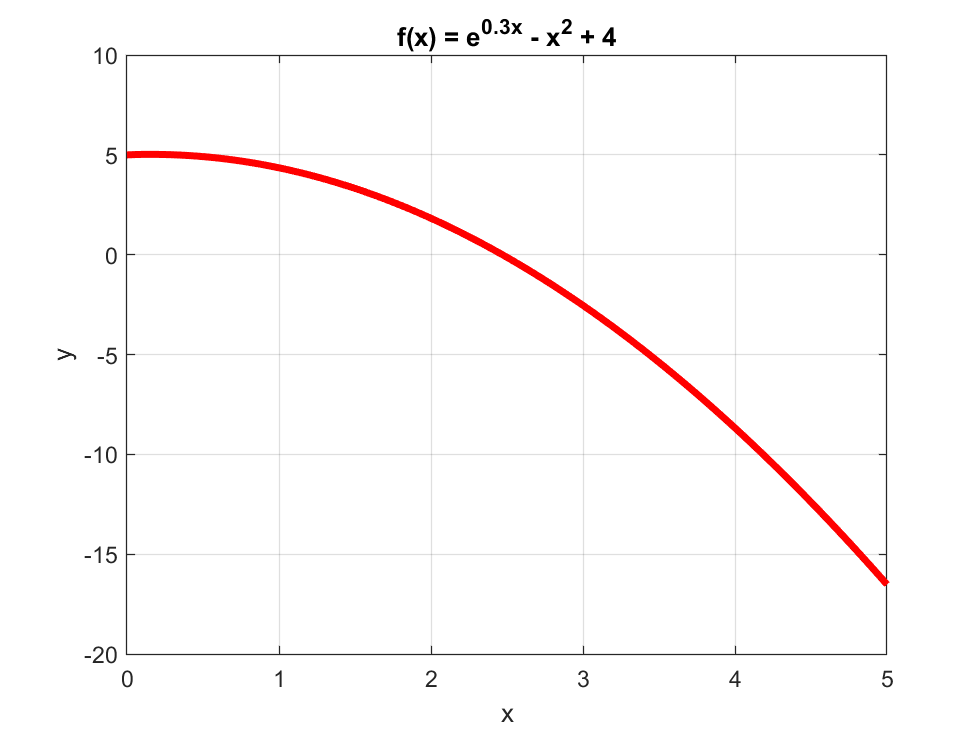

f = @(x) exp(0.3*x) - x.^2 + 4;

x = linspace(0, 5, 100);
plot(x, f(x), 'r', 'linewidth', 3)
grid on
xlabel('x')
ylabel('y')
title('f(x) = e^0^.^3^x - x^2 + 4')

Solución de la ecuación

xa = 1;
xb = 5;
errmax = 0.1;
[xr, fr, err] = bisection(f, xa, xb, errmax);

xa: 1  xb: 5  xm: 3  fa: 4.3499  fb: -16.5183  fm: -2.5404  error: 66.6667
xa: 1  xb: 3  xm: 2  fa: 4.3499  fb: -2.5404  fm: 1.8221  error: 50
xa: 2  xb: 3  xm: 2.5  fa: 1.8221  fb: -2.5404  fm: -0.133  error: 20
xa: 2  xb: 2.5  xm: 2.25  fa: 1.8221  fb: -0.133  fm: 0.90153  error: 11.1111
xa: 2.25  xb: 2.5  xm: 2.375  fa: 0.90153  fb: -0.133  fm: 0.39846  error: 5.2632
xa: 2.375  xb: 2.5  xm: 2.4375  fa: 0.39846  fb: -0.133  fm: 0.13627  error: 2.5641
xa: 2.4375  xb: 2.5  xm: 2.4688  fa: 0.13627  fb: -0.133  fm: 0.0025193  error: 1.2658
xa: 2.4688  xb: 2.5  xm: 2.4844  fa: 0.0025193  fb: -0.133  fm: -0.065019  error: 0.62893
xa: 2.4688  xb: 2.4844  xm: 2.4766  fa: 0.0025193  fb: -0.065019  fm: -0.031195  error: 0.31546
xa: 2.4688  xb: 2.4766  xm: 2.4727  fa: 0.0025193  fb: -0.031195  fm: -0.014324  error: 0.15798
xa: 2.4688  xb: 2.4727  xm: 2.4707  fa: 0.0025193  fb: -0.014324  fm: -0.0058988  error: 0.079051


disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = 2.4707  f(x) = -0.0058988  Error:0.079051%


#### Ejemplo 5


$$2\cos\left(x\right)-\frac{\sqrt{x}}{2}=1$$
 

Definición de la función y su gráfica

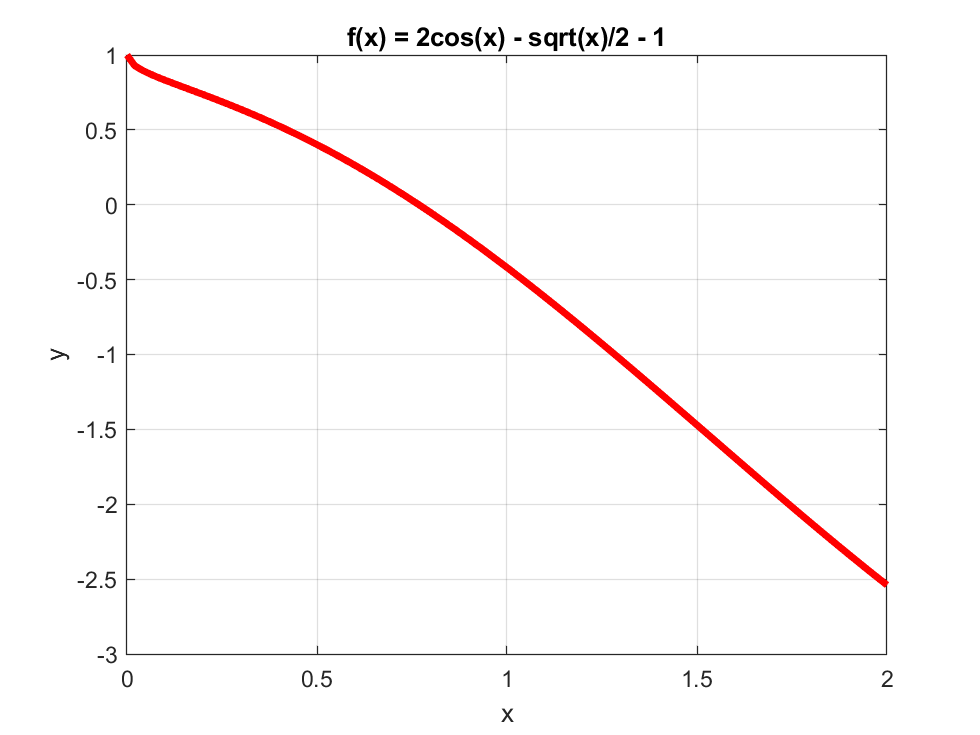

f = @(x) 2*cos(x) - sqrt(x)/2 - 1;

x = linspace(0, 2, 100);
plot(x, f(x), 'r', 'linewidth', 3)
grid on
xlabel('x')
ylabel('y')
title('f(x) = 2cos(x) - sqrt(x)/2 - 1')

Solución de la ecuación

xa = 0;
xb = 2;
errmax = 0.1;
[xr, fr, err] = bisection(f, 0, 2, 0.1);

xa: 0  xb: 2  xm: 1  fa: 1  fb: -2.5394  fm: -0.4194  error: 100
xa: 0  xb: 1  xm: 0.5  fa: 1  fb: -0.4194  fm: 0.40161  error: 100
xa: 0.5  xb: 1  xm: 0.75  fa: 0.40161  fb: -0.4194  fm: 0.030365  error: 33.3333
xa: 0.75  xb: 1  xm: 0.875  fa: 0.030365  fb: -0.4194  fm: -0.18571  error: 14.2857
xa: 0.75  xb: 0.875  xm: 0.8125  fa: 0.030365  fb: -0.18571  fm: -0.075323  error: 7.6923
xa: 0.75  xb: 0.8125  xm: 0.78125  fa: 0.030365  fb: -0.075323  fm: -0.021874  error: 4
xa: 0.75  xb: 0.78125  xm: 0.76563  fa: 0.030365  fb: -0.021874  fm: 0.0043988  error: 2.0408
xa: 0.76563  xb: 0.78125  xm: 0.77344  fa: 0.0043988  fb: -0.021874  fm: -0.0086995  error: 1.0101
xa: 0.76563  xb: 0.77344  xm: 0.76953  fa: 0.0043988  fb: -0.0086995  fm: -0.0021408  error: 0.50761
xa: 0.76563  xb: 0.76953  xm: 0.76758  fa: 0.0043988  fb: -0.0021408  fm: 0.0011313  error: 0.25445
xa: 0.76758  xb: 0.76953  xm: 0.76855  fa: 0.0011313  fb: -0.0021408  fm: -0.00050415  error: 0.12706
xa: 0.76758  xb: 0.76855  xm:

disp("x = " + xr + "  f(x) = " + fr + "  Error:" + err + "%")

x = 0.76807  f(x) = 0.00031375  Error:0.063573%


#### Método de bisección

function [xr, fr, err] = bisection(f, xa, xb, errmax)
% Función que resuelve una ecuación de una variable por 
% el método de bisección.
%
% Entradas:
%   f         Función que define la ecuación a resolver.
%   xa        Valor inicial del rango de la ecuación.
%   xb        Valor final del rango de la ecuación.
%   errmax    Máximo error permitido para la solución.
%
% Salidas:
%   xr        Raíz de la ecuación encontrada.
%   fr        Valor de la ecuación en la raíz encontrada.
%   err       Error porcentual de la última iteración.

% Verifica que los parámetros de entrada sean válidos.
if nargin ~= 4
    error('Cantidad de parámetros de entrada no válido.')
end

if ~isscalar(xa) || ~isnumeric(xa)
    error('El valor xa debe ser numérico y escalar.')
end

if ~isscalar(xb) || ~isnumeric(xb)
    error('El valor xb debe ser numérico y escalar.')
end

if ~isscalar(errmax) || ~isnumeric(errmax) || errmax <= 0
    error('El valor errmax debe ser numérico, escalar y mayor a cero.')
end

% Evalúa la función en los puntos iniciales.
fa = f(xa);
fb = f(xb);

% Verifica si los valores iniciales son una solución.
if fa == 0
    xr = xa;
    fr = 0;
    err = 0;
    return 
end

if fb == 0
    xr = xb;
    fr = 0;
    err = 0;
    return 
end

% Verifica que entre los valores dados haya una solución.
if fa*fb > 0
    error('Valores iniciales no válidos.')
end

% Algoritmo de bisección.
err = 100*errmax;
xm = xa;
while err > errmax
    
    % Valor anterior de xm
    xma = xm;
    
    % Nuevo valor de xm
    xm = (xa + xb)/2;
    fm = f(xm);
    
    % Calcula el error actual.
    err = 100*(abs(xm - xma)/max([abs(xm), eps]));
    
    % Despliega los valores actuales.
    disp("xa: " + xa + "  xb: " + xb + "  xm: " + xm + ...
        "  fa: " + fa + "  fb: " + fb + "  fm: " + fm + "  error: " + err)
    
    % Actualiza los límites del intervalo.
    if fa*fm < 0
        % En este caso, xb se mueve a la posición xm.
        xb = xm;
        fb = fm;
    elseif fb*fm < 0
        % En este caso, xa se mueve a la posición xm.
        xa = xm;
        fa = fm;
    else
        % En este caso tenemos una solución en xm.
        err = 0;
    end     
    
end

% Guarda el resultado en las variables de salida.
xr = xm;
fr = fm;
end